# Regular Method

% Load 3D mesh and Jacobian
tic
load meshes/subject10_stnd.mat
load Jacobian/subject10_stnd_J
toc 

Elapsed time is 29.570510 seconds.


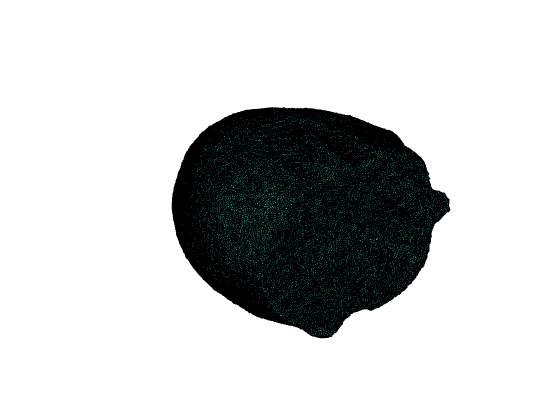

% plot 3D mesh
figure, plotmesh_fiducials(mesh);

%% Model activation 10 mm radius in gray matter only
activation_centre = [103 132 157];

blob_indx = find(sqrt(sum((mesh.nodes-activation_centre).^2,2))<=10);
gray_indx = find(mesh.region==4);
blob_indx = intersect(blob_indx,gray_indx);

% set label for viewing
mesh_blob = mesh;
mesh_blob.region(blob_indx) = 10;

delta_mua = zeros(size(J.complete,2),1);
delta_mua(blob_indx) = 1;

tic
rhs = J.complete*delta_mua;

%% reconstruct from simulated data
Hess = J.complete*J.complete';
reg = eye(size(Hess)).*max(diag(Hess)).*1e-1;

mua_recon = J.complete'*inv(Hess+reg)*rhs;
toc

Elapsed time is 313.434854 seconds.


Error using memory
Function MEMORY is not available on this platform.

figure, plot3dmesh(mesh, mua_recon);

whos J

  Name      Size                 Bytes  Class     Attributes

  J         1x1             6732353400  struct              

